% Settings

rng(13)

clc
clear all
close all
format long

% Parameters
%-----------

disctr = 0; % display controler

trials = 1e0; 

P_tx = 0; % transmit power in dBm

NUM_POSITIONS = 100;

NUM_CHANNELS = 5; % K : number of channels
NUM_USER_PAIRS = 4; % N: tactical nodes

% Carrier frequency (in GHz)
fc = 3; % GHz

% 3GPP Urban Micro in 3GPP TS 36.814
% NLoS path-loss component based on distance, x is in meter
% pathloss_NLOS = @(x) db2pow(-22.7 - 26*log10(fc) - 36.7*log10(x));

% Simplified NLoS path-loss model with path-loss exponent ple
% d in meters
ple = 3; % Suburban / Light Urban with Nakagami
pathloss_NLOS = @(d) 1 ./ (d.^ple);


antenna_gain_Tx = db2pow(0); % Source antenna gain, dBi
antenna_gain_Rx = db2pow(0); % Destination antenna gain, dBi

snr_avg_db = 94 + P_tx; % transmit SNR [dB], same as in exhaustive search
                  % snr_db = P_S_dBm - sigma2dBm; dB = dBm - dBm
                  % key para of the sim

snr_avg = db2pow(snr_avg_db);

BW = 20e6; % Bandwidth
noiseFiguredB = 10; % Noise figure (in dB)

% Compute the noise power in dBm
sigma2dBm = -174 + 10*log10(BW) + noiseFiguredB; % = - 120 dBm

Pt_dBm = snr_avg_db + sigma2dBm; % compute transmit power from SNR

% Assigning positions
%--------------------

pos_jammer = load('data_pos_RWP.csv');
pos_nodes = load('data_pos_RPGM.csv');

pos_J = pos_jammer(1:NUM_POSITIONS, :); % Jammer

pos_Tx1 = pos_nodes(1:NUM_POSITIONS, 5:6); % position of Tx1
pos_Rx1 = pos_nodes(1:NUM_POSITIONS, 7:8); % position of Rx1

pos_Tx2 = pos_nodes(1:NUM_POSITIONS, 9:10); % position of Tx2
pos_Rx2 = pos_nodes(1:NUM_POSITIONS, 11:12); % position of Rx2

pos_Tx3 = pos_nodes(1:NUM_POSITIONS, 13:14); % position of Tx3
pos_Rx3 = pos_nodes(1:NUM_POSITIONS, 15:16); % position of Rx3

pos_Tx4 = pos_nodes(1:NUM_POSITIONS, 17:18); % position of Tx4
pos_Rx4 = pos_nodes(1:NUM_POSITIONS, 19:20); % position of Rx4

pos_Tx5 = pos_nodes(1:NUM_POSITIONS, 21:22); % position of Tx4
pos_Rx5 = pos_nodes(1:NUM_POSITIONS, 23:24); % position of Rx4

H_all = []; %zeros(NUM_SAMPLES, NUM_CHANNELS*NUM_USERS);
G_all = [];
rate_all = [];
opt_rate_all = [];



%% Channel modeling

for tt = 1:trials
    opt_sum_rate = 0;
    for idx = 1:NUM_POSITIONS

        % Compute distances
        %------------------
        d_Tx1_Rx1 = sqrt(sum((pos_Tx1 - pos_Rx1).^2 , 2));
        d_Tx2_Rx2 = sqrt(sum((pos_Tx2 - pos_Rx2).^2 , 2));
        d_Tx3_Rx3 = sqrt(sum((pos_Tx3 - pos_Rx3).^2 , 2));
        d_Tx4_Rx4 = sqrt(sum((pos_Tx4 - pos_Rx4).^2 , 2));
        d_Tx5_Rx5 = sqrt(sum((pos_Tx5 - pos_Rx5).^2 , 2));

        d_Tx1_J = sqrt(sum((pos_Tx1 - pos_J).^2 , 2));
        d_Tx2_J = sqrt(sum((pos_Tx2 - pos_J).^2 , 2));
        d_Tx3_J = sqrt(sum((pos_Tx3 - pos_J).^2 , 2));
        d_Tx4_J = sqrt(sum((pos_Tx4 - pos_J).^2 , 2));
        d_Tx5_J = sqrt(sum((pos_Tx5 - pos_J).^2 , 2));

        %% SIMULATION

        % Nakagami scale parameter

        m_Tx1_Rx1 = 3 + rand;
        m_Tx2_Rx2 = 3 + rand;
        m_Tx3_Rx3 = 3 + rand;
        m_Tx4_Rx4 = 3 + rand;
        m_Tx5_Rx5 = 3 + rand;

        m_Tx1_J = 3 + rand;
        m_Tx2_J = 3 + rand;
        m_Tx3_J = 3 + rand;
        m_Tx4_J = 3 + rand;
        m_Tx5_J = 3 + rand;

        % Nakagami spread parameter

        Omega_Tx1_Rx1 = 1;
        Omega_Tx2_Rx2 = 1;
        Omega_Tx3_Rx3 = 1;
        Omega_Tx4_Rx4 = 1;
        Omega_Tx5_Rx5 = 1;

        Omega_Tx1_J = 1;
        Omega_Tx2_J = 1;
        Omega_Tx3_J = 1;
        Omega_Tx4_J = 1;
        Omega_Tx5_J = 1;
        

        %% Legitimate channel


        % Tx1-Rx1 channel
        PL_Tx1_Rx1 = pathloss_NLOS(d_Tx1_Rx1)*antenna_gain_Tx*antenna_gain_Rx;
        h_Tx1_Rx1 = sqrt(PL_Tx1_Rx1) * ...
            random(makedist('Nakagami', 'mu', m_Tx1_Rx1, 'omega', Omega_Tx1_Rx1), 1, NUM_CHANNELS);

        % Tx2-Rx2 channel
        PL_Tx2_Rx2 = pathloss_NLOS(d_Tx2_Rx2)*antenna_gain_Tx*antenna_gain_Rx;
        h_Tx2_Rx2 = sqrt(PL_Tx2_Rx2) * ...
            random(makedist('Nakagami', 'mu', m_Tx2_Rx2, 'omega', Omega_Tx2_Rx2), 1, NUM_CHANNELS);

        % Tx3-Rx3 channel
        PL_Tx3_Rx3 = pathloss_NLOS(d_Tx3_Rx3)*antenna_gain_Tx*antenna_gain_Rx;
        h_Tx3_Rx3 = sqrt(PL_Tx3_Rx3) * ...
            random(makedist('Nakagami', 'mu', m_Tx3_Rx3, 'omega', Omega_Tx3_Rx3), 1, NUM_CHANNELS);

        % Tx4-Rx4 channel
        PL_Tx4_Rx4 = pathloss_NLOS(d_Tx4_Rx4)*antenna_gain_Tx*antenna_gain_Rx;
        h_Tx4_Rx4 = sqrt(PL_Tx4_Rx4) * ...
            random(makedist('Nakagami', 'mu', m_Tx4_Rx4, 'omega', Omega_Tx4_Rx4), 1, NUM_CHANNELS);

        % Tx5-Rx5 channel
        PL_Tx5_Rx5 = pathloss_NLOS(d_Tx5_Rx5)*antenna_gain_Tx*antenna_gain_Rx;
        h_Tx5_Rx5 = sqrt(PL_Tx5_Rx5) * ...
            random(makedist('Nakagami', 'mu', m_Tx5_Rx5, 'omega', Omega_Tx5_Rx5), 1, NUM_CHANNELS);
       
        %% Jamming channels

        % Tx1 -> Jammer
        PL_Tx1_J = pathloss_NLOS(d_Tx1_J)*antenna_gain_Tx*antenna_gain_Rx; % S->D link
        h_Tx1_J = sqrt(PL_Tx1_J) * ...
            random(makedist('Nakagami', 'mu', m_Tx1_J, 'omega', Omega_Tx1_J), 1, NUM_CHANNELS);

        % Tx2 -> Jammer
        PL_Tx2_J = pathloss_NLOS(d_Tx2_J)*antenna_gain_Tx*antenna_gain_Rx; % S->D link
        h_Tx2_J = sqrt(PL_Tx2_J) * ...
            random(makedist('Nakagami', 'mu', m_Tx2_J, 'omega', Omega_Tx2_J), 1, NUM_CHANNELS);

        % Tx3 -> Jammer
        PL_Tx3_J = pathloss_NLOS(d_Tx3_J)*antenna_gain_Tx*antenna_gain_Rx; % S->D link
        h_Tx3_J = sqrt(PL_Tx3_J) * ...
            random(makedist('Nakagami', 'mu', m_Tx3_J, 'omega', Omega_Tx3_J), 1, NUM_CHANNELS);
        
        % Tx4 -> Jammer
        PL_Tx4_J = pathloss_NLOS(d_Tx4_J)*antenna_gain_Tx*antenna_gain_Rx; % S->D link
        h_Tx4_J = sqrt(PL_Tx4_J) * ...
            random(makedist('Nakagami', 'mu', m_Tx4_J, 'omega', Omega_Tx4_J), 1, NUM_CHANNELS);
        
        % Tx5 -> Jammer
        PL_Tx5_J = pathloss_NLOS(d_Tx5_J)*antenna_gain_Tx*antenna_gain_Rx; % S->D link
        h_Tx5_J = sqrt(PL_Tx5_J) * ...
            random(makedist('Nakagami', 'mu', m_Tx5_J, 'omega', Omega_Tx5_J), 1, NUM_CHANNELS);
        
        % ------------
        
        h_Tx_all = [h_Tx1_Rx1(idx,:); ...
            h_Tx2_Rx2(idx,:); h_Tx3_Rx3(idx,:); ...
            h_Tx4_Rx4(idx,:); h_Tx5_Rx5(idx,:)];
        h_Tx = h_Tx_all(1:NUM_USER_PAIRS, :);
        
        % benign user channel (Tx->Rx) matrix
        % H = rand(NUM_USER_PAIRS, NUM_CHANNELS) .* ...
        %     h_Tx;
        H = h_Tx;
        
        h_Tx_J_all = [h_Tx1_J(idx,:); ...
            h_Tx2_J(idx,:); h_Tx3_J(idx,:); ...
            h_Tx4_J(idx,:); h_Tx5_J(idx,:)];
        h_Tx_J = h_Tx_J_all(1:NUM_USER_PAIRS, :);
        % jammer channel (Tx->J) matrix
        G = h_Tx_J;

        % compute all SNRs
        snr_user = snr_avg .* abs(H).^2 ; % benign SNRs
        snr_jammer = snr_avg .* abs(G).^2 ; % observable jammer SNRs

        % benign rate of all users
        rate_user = log2(1+snr_user); % all, before jamming
        if disctr == 1
            fprintf('Rate before jamming: \n');
            disp(rate_user);
        end

        % observable rate at the jammer
        rate_jammer = log2(1+snr_jammer);

        %% Simulation of jamming attack

        % possible channel allocation
        channel_vector = 1:NUM_CHANNELS;
        action_all = ExhaustiveSearch_npermutek(channel_vector, NUM_USER_PAIRS);
        
%         ida_random = randi([1,length(action_all)]); % for RANDOM alg
        
        sum_rate = zeros(length(action_all),1); % reset for each position loop

        % loop all over the possible actions (= FBAs)
        for ida = 1:length(action_all)
            action = action_all(ida,:); % a single action
            if disctr == 1
                fprintf('The action is: \n')
                disp(action)
            end
            
            
%             action = action_all(ida_random,:); % RANDOM a single action

            % compute rates of active channels only
            rate_user_active = zeros(NUM_USER_PAIRS, NUM_CHANNELS);
            rate_jammer_active = zeros(NUM_USER_PAIRS, NUM_CHANNELS);

            for ii = 1:length(action)
                rate_user_active(ii,action(ii)) = rate_user(ii,action(ii));
                rate_jammer_active(ii,action(ii)) = rate_jammer(ii,action(ii));
            end
            if disctr == 1
                fprintf('Active rate before jamming: \n')
                disp(rate_user_active)
            end

            % % find the jammed channel (including all pairs)
            % % the jammed channel is the channel with highest active jammer rate
            % [~ , c_J] = ...
            %     find(rate_jammer_active == max(rate_jammer_active,[],'all'));
            % f_J = c_J; % the jammed channel
            

            % select one pair max only
            [~, lin] = max(rate_jammer_active(:));
            [~, f_J] = ind2sub(size(rate_jammer_active), lin);

            if disctr == 1
                fprintf('The jammed channel is f%d \n', f_J)
            end

            % update benign channel matrix with jammed channel
            rate_user_active(:,f_J) = 0;
            if disctr == 1
                fprintf('Rate after jamming: \n');
                disp(rate_user_active);
            end

            % compute achievable rate of jamming-free users
            for index = 1:NUM_USER_PAIRS
                rate_each_user(index) = rate_user_active(index, action(index));
                if disctr == 1
                    fprintf('Rate of user %d is %.6f \n', index, rate_each_user(index));
                end
            end

            % compute sum achievable rate
            sum_rate(ida) = sum(rate_each_user);
            if disctr == 1
                fprintf('Sum rate is: %.6f \n', sum_rate(ida))
                fprintf('-------------------------------------------\n')
            end
        end

        % maximum jamming-free sum-rate
        if disctr == 1
            fprintf('Benign channel matrix \n')
            disp(H)
            
            fprintf('Jamming channel matrix \n')
            disp(G)
        end

        % opt_sum_rate = max(sum_rate);
        % fprintf('Maximum sum rate is: %.6f \n', opt_sum_rate)

        %---------
        % --- after loop: find optimal sum rate and corresponding ida(s) ---
        [opt_sum_rate, ida_opt_first] = max(sum_rate);       % ida_opt_first is the first index of a maximum
        ida_all_opt = find(sum_rate == opt_sum_rate);       % all indices that attain the maximum (ties)
        
        if disctr == 1
            fprintf('Maximum sum rate is: %.6f \n', opt_sum_rate)
            fprintf('Index (first) that gives opt_sum_rate: %d\n', ida_opt_first)
            fprintf('All indices that give opt_sum_rate: '); disp(ida_all_opt)
            
            % corresponding best action(s)
            best_action = action_all(ida_opt_first, :);
            fprintf('Best action (first): \n'); disp(best_action)
    
            % if you want to list all tied best actions:
            best_actions_all = action_all(ida_all_opt, :);
            fprintf('All best actions (if tie): \n'); disp(best_actions_all)
        end
        %---------

        H_rsp = reshape(H', 1, []); % matrix to vector, to input to Python
        G_rsp = reshape(G', 1, []);

        H_all = [H_all; H_rsp]; % 2D matrix to input to Python
        G_all = [G_all; G_rsp];
        rate_all = [rate_all; opt_sum_rate];
        opt_rate_all = [opt_rate_all; opt_sum_rate];

        


    end
end


disp('-----------------------------------------------------------------')

-----------------------------------------------------------------


fprintf('With K = %d bands, N = %d nodes \n', NUM_CHANNELS, NUM_USER_PAIRS)

With K = 5 bands, N = 4 nodes 


fprintf('Pt = %d dBm, noise = %d dBm', Pt_dBm, sigma2dBm )

Pt = 3.010300e+00 dBm, noise = -9.098970e+01 dBm

% fprintf('Locations = %d positions \n', NUM_POSITIONS)
fprintf('Avg. optimal sum-rate = %.5f [b/s/Hz] \n', mean(opt_rate_all))

Avg. optimal sum-rate = 21.99522 [b/s/Hz] 


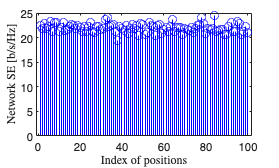



%% Plot
figure;
stem(1:NUM_POSITIONS, rate_all, 'bo-'); hold on
% stem(1:NUM_POSITIONS, mean(rate_all)*ones(1,NUM_POSITIONS), 'r-')

xlabel('Index of positions', 'interpreter', 'latex')
ylabel('Network SE [b/s/Hz]', 'interpreter', 'latex')

% legend('Instantaneous SE', ...
    % 'location', 'best', 'interpreter', 'latex')
% axis([-Inf Inf 0 20])

% %
% figure;
% scatter(pos_Tx0(:,1), pos_Tx0(:,2), ...
%     mean(rate_all)*ones(1,NUM_POSITIONS), 'o'); hold on
% % plot average OP plane
% [X,Y] = meshgrid(min(min(pos_Tx0)):.5:max(max(pos_Tx0)));
% Z = ( 0.*Y + 0.*X) + mean(rate_all);
% s = surf(X,Y,Z,'FaceAlpha',0.2);
% legend('Sim.', 'Ana.')
% xlabel('x-pos')
% ylabel('y-pos')
% zlabel('Sumr rate')


%% Save data
save('data_H_all.mat', 'H_all')
save('data_G_all.mat', 'G_all')
